addpath(genpath('/datascience/projects/statisticallyfit/github/MATLAB/MatlabTutorial/AMTH250_NumericalMatlab/Root Finding'))

Question 1

n = 21, nMax = 21, solution = 0.7390947


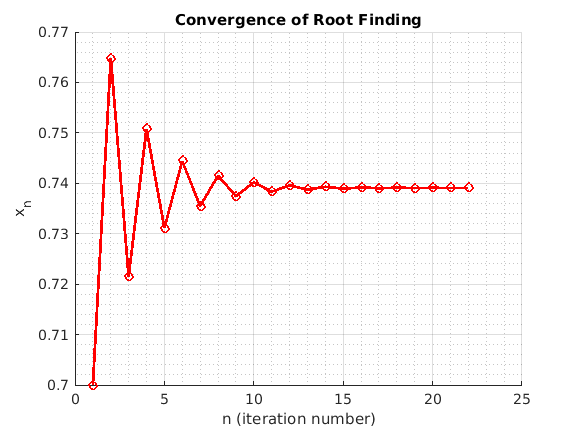

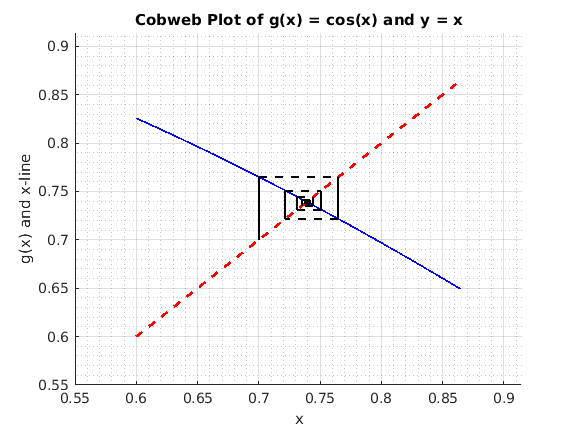

g = @(x) cos(x);
fixedPointRoot(g, 0.7, 6);

Question 2

f=  @(x) x.^4 - x - 0.12

f = function_handle with value:
    @(x)x.^4-x-0.12


  1    -1.000000    1.000000    0.000000   -0.120000    1.000000
  2    -1.000000    0.000000   -0.500000    0.442500    0.500000
  3    -0.500000    0.000000   -0.250000    0.133906    0.250000
  4    -0.250000    0.000000   -0.125000    0.005244    0.125000
  5    -0.125000    0.000000   -0.062500   -0.057485    0.062500
  6    -0.125000   -0.062500   -0.093750   -0.026173    0.031250
  7    -0.125000   -0.093750   -0.109375   -0.010482    0.015625
  8    -0.125000   -0.109375   -0.117188   -0.002624    0.007812
  9    -0.125000   -0.117188   -0.121094    0.001309    0.003906
 10    -0.121094   -0.117188   -0.119141   -0.000658    0.001953
 11    -0.121094   -0.119141   -0.120117    0.000325    0.000977
 12    -0.120117   -0.119141   -0.119629   -0.000166    0.000488
 13    -0.120117   -0.119629   -0.119873    0.000080    0.000244
 14    -0.119873   -0.119629   -0.119751   -0.000043    0.000122
 15    -0.119873   -0.119751   -0.119812    0.000018    0.000061
 16    -0.119812   -0.119

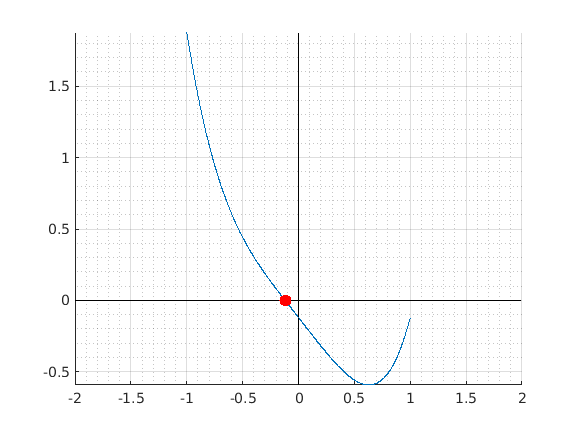

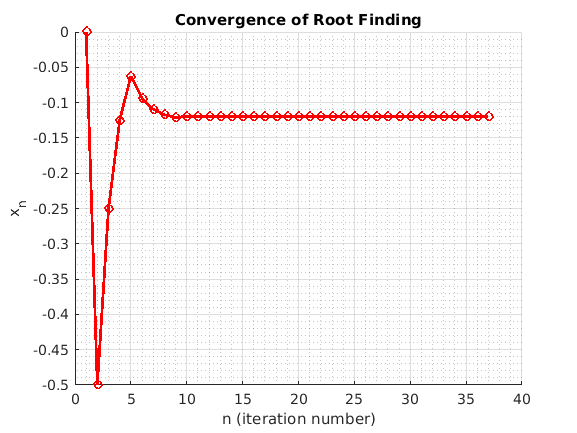

bisectRoot(f, -1, 1, 10);

g = @(x) x.^4 - 0.12

g = function_handle with value:
    @(x)x.^4-0.12


n = 5, solution = -0.119794060


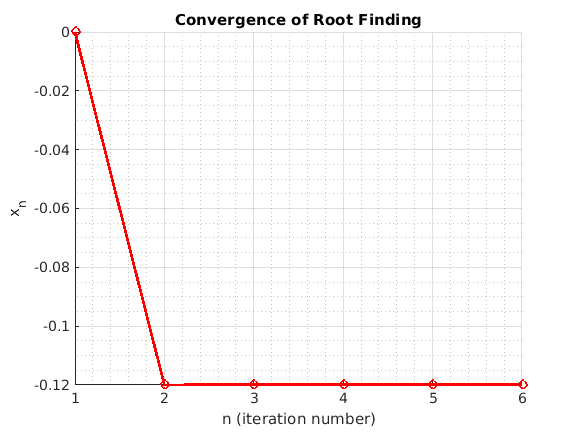

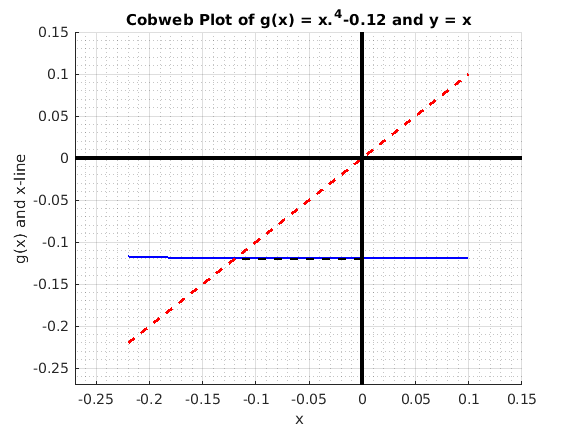

fixedPointRoot(g, 0, 8);

convergence is fast since graph near the solution is almost horizontal so |g'(x0)| is very small

n = 6, solution = -0.119794060


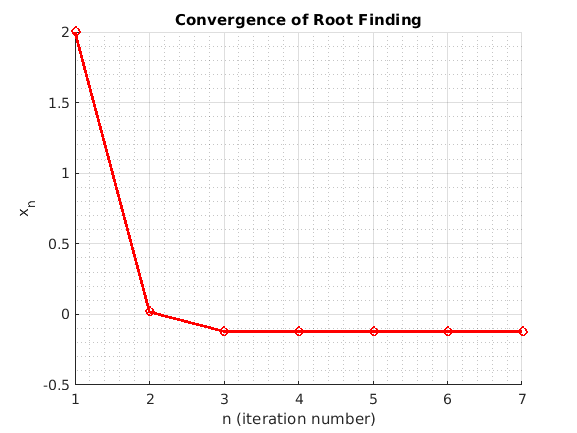

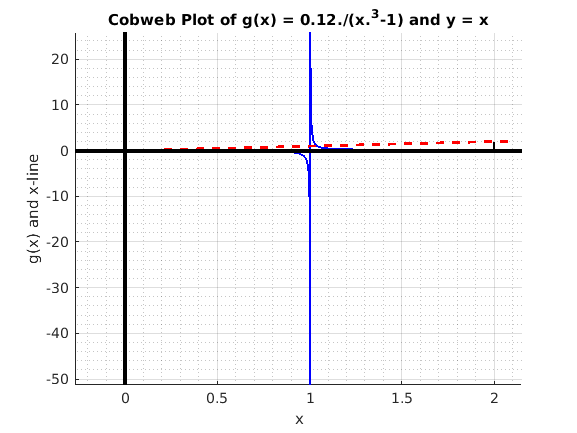

% lipshutz continuous function. 
g = @(x) 0.12 ./ (x .^ 3 - 1);
fixedPointRoot(g, 2, 8);

Question 3

n = 33, solution = 0.0000010


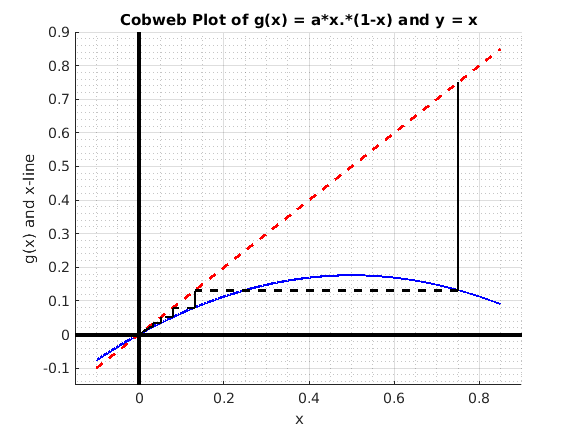

% when x0 = 0, then 0 < a < 1 for 
% convergence. WHen 0 < a< 1, xSOl = 0
a = 0.7;
g = @(x) a*x.*(1-x);
fixedPointRoot(g, 0.75, 6);

n = 32, solution = 0.00000000004


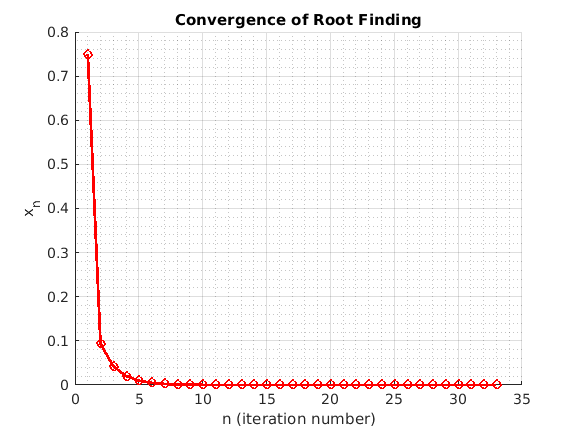

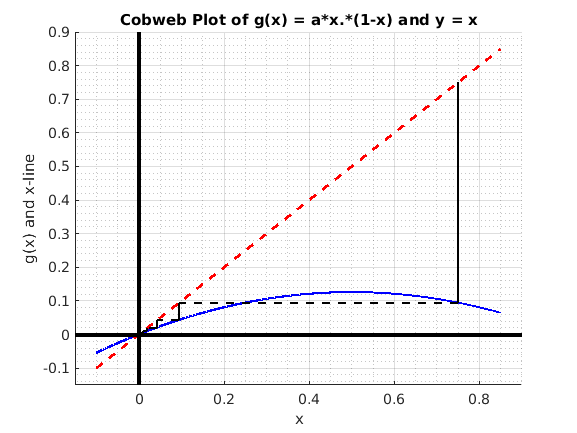

a = 0.5;
g = @(x) a*x.*(1-x);
fixedPointRoot(g, 0.75, 10);

n = 50, solution = 0.09095125583


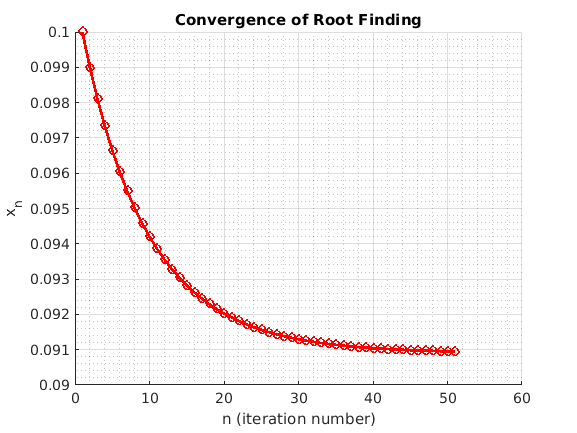

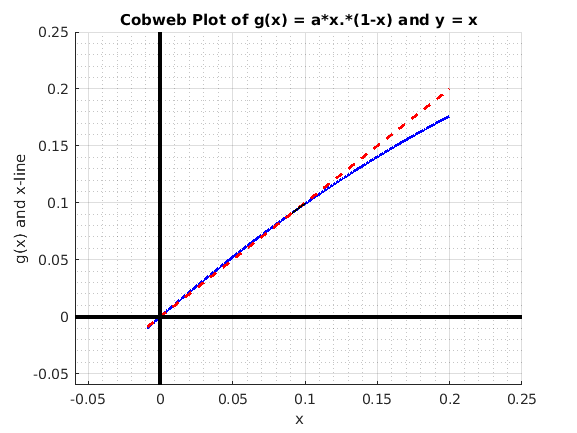

% when x0 = (a-1)/a, then 1 < a < 3
% for convergence of fixed point. 
a = 1.1;
g = @(x) a*x.*(1-x);
fixedPointRoot(g, 0.1, 10);

% real sol = x = (a-1)/a = 0.090909.

n = 6, solution = 0.5000000


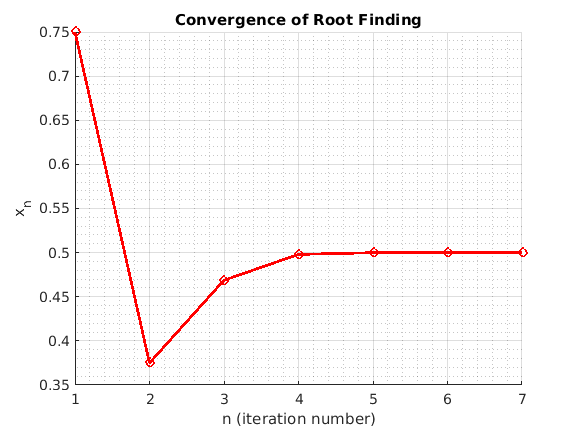

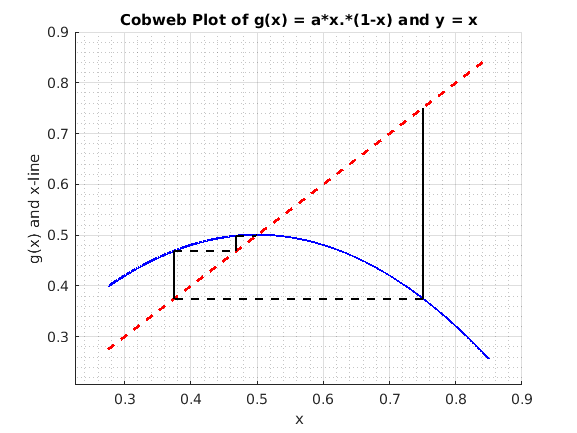

a = 2;
g = @(x) a*x.*(1-x);
fixedPointRoot(g, 0.75, 6);

% real sol = x = (a-1)/a = 1/2

Now there is no convergence outside these bounds but choosing a >= 3 something interesting happens, if we first remove fluctuations. 

[s, x, g] = logisticMapCase(3.2);

n = 500, solution = 0.7994555


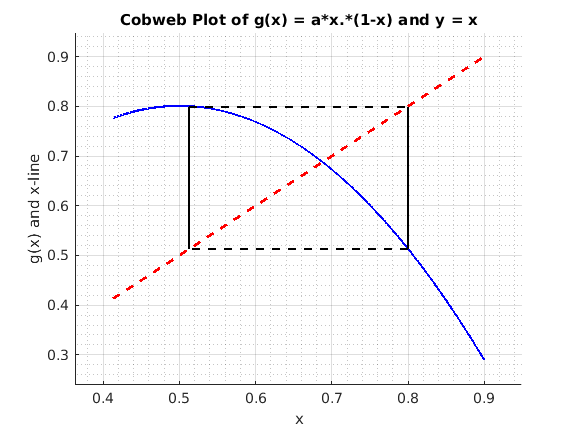

plotCobweb(g, x)

[~, x, g] = logisticMapCase(3.5);

n = 150, solution = 0.8749973


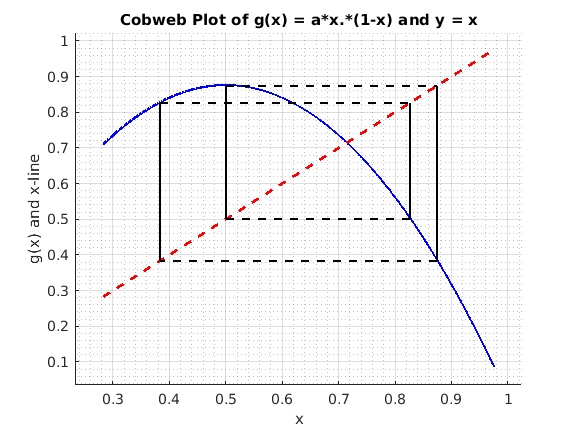

plotCobweb(g, x);

[~, x, g] = logisticMapCase(3.55);

n = 50, solution = 0.8816901


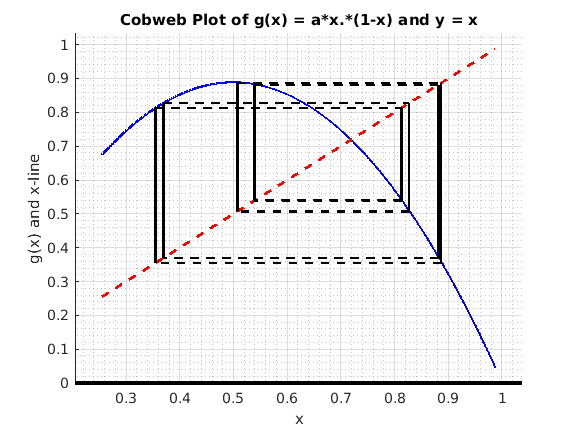

plotCobweb(g, x);

[~, x, g] = logisticMapCase(3.7);

n = 50, solution = 0.8444221


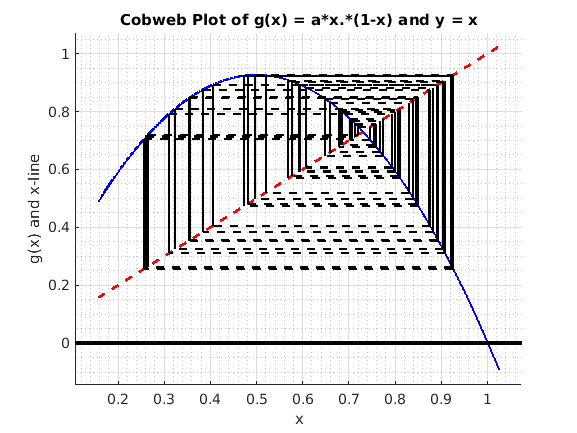

plotCobweb(g, x);

 Question 4

For x < 0: complete divergence = going to -Inf and then Inf right after. Then NaNs all the way. 

g = @(x) 1 - 5*x + (15/2)*x.^2-(5/2)*x.^3;
[sol, x] = fixedPointRoot(g, -0.2, 10);

n = 50, solution = NaN


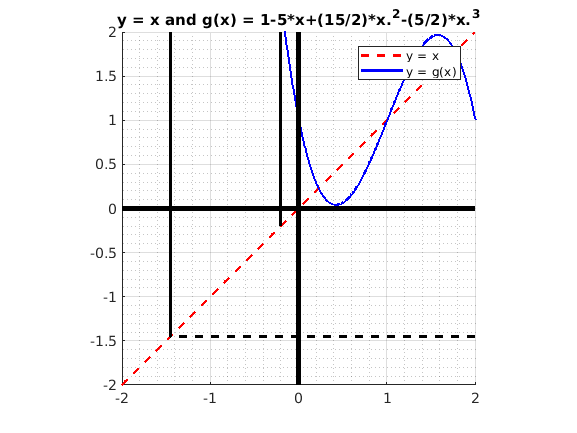


plotCobwebInterval(g, -2, 2, -0.2);

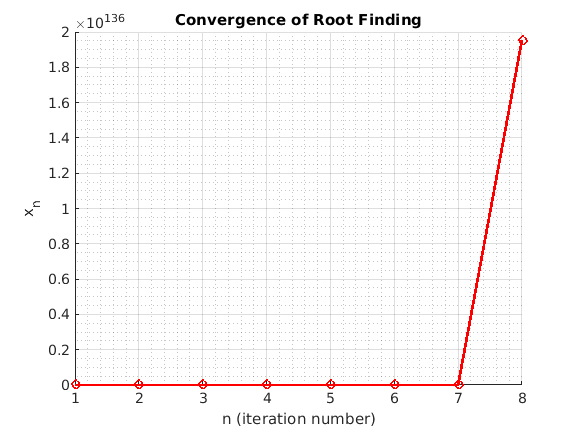

plotConvergence(x);

For x -> 0- (zero from the left) we get a cycle near solution of x = 1.7745. (see where all the black is)

[sol, x] = fixedPointRoot(g, -0.01, 10);

n = 50, solution = 1.59141140173


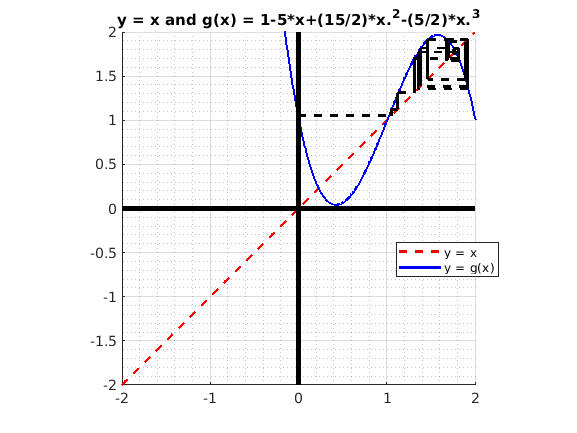


plotCobwebInterval(g, -2, 2, -0.01);

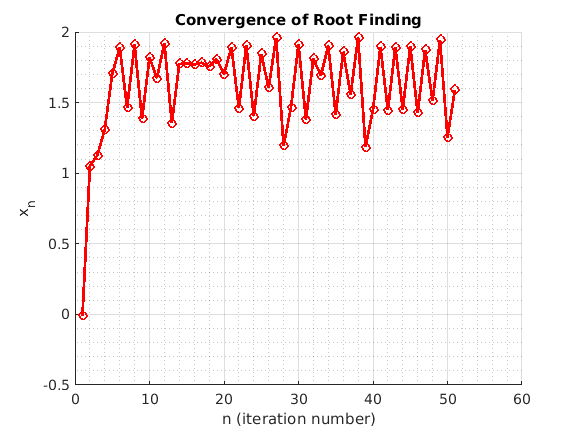

plotConvergence(x);

For 0 < x < 1 (still no solution)

for x -> 0+

[~, x] = fixedPointRoot(g, 0.01, 10);

n = 50, solution = 0.81128482013


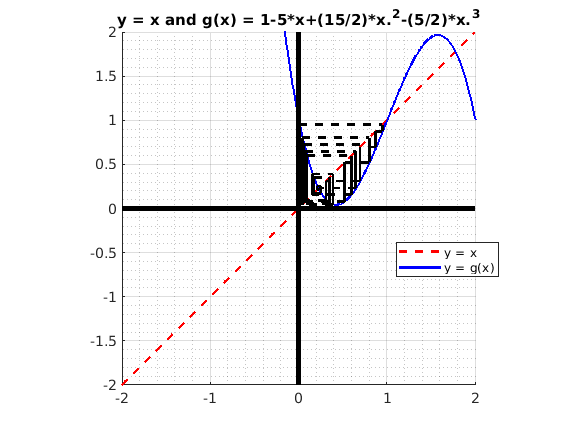

plotCobwebInterval(g, -2,2, 0.01);

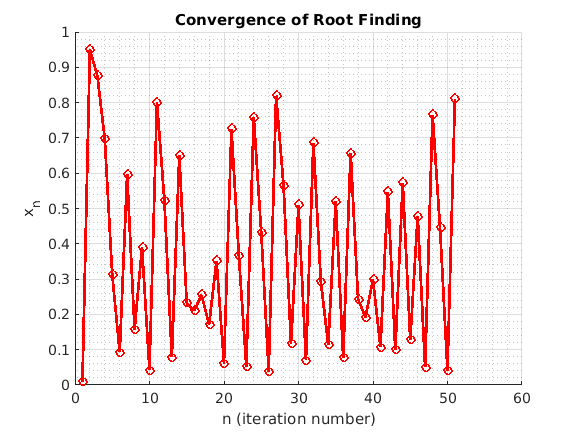

plotConvergence(x);

for x -> 1- (to 1 from the left) we get cycle around the value x = 0.2255

[~, x] = fixedPointRoot(g, 0.99, 10);

n = 50, solution = 0.15416015818


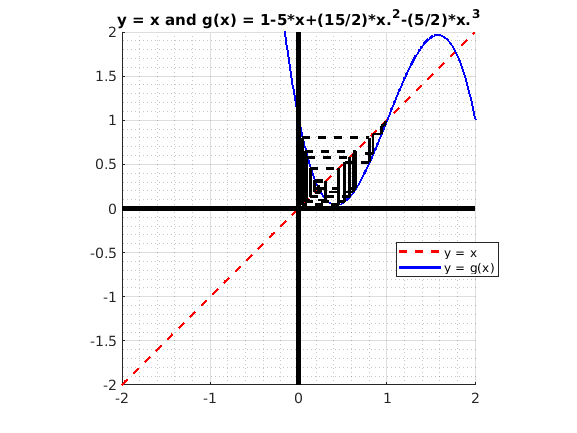

plotCobwebInterval(g, -2,2, 0.99);

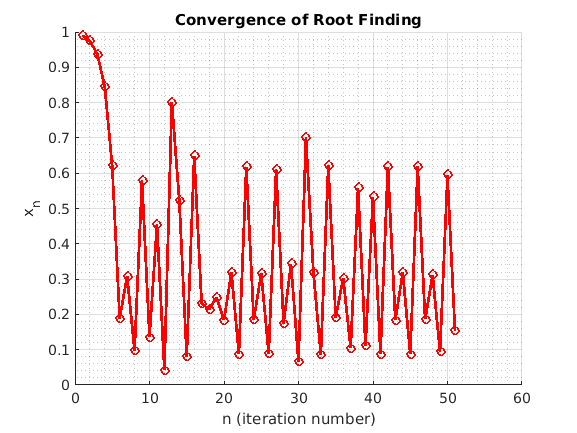

plotConvergence(x);

For 1 < x < 2 (for x -> 2- from the left, we get cycle around x = 1.7745)

[~, x] = fixedPointRoot(g, 1.9, 10);

n = 50, solution = 1.25627137810


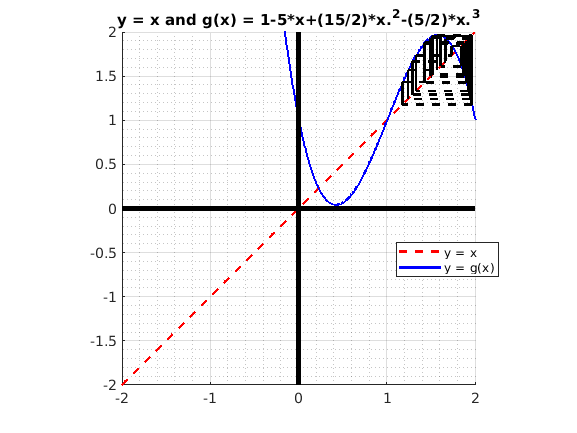

plotCobwebInterval(g, -2, 2, 1.9)

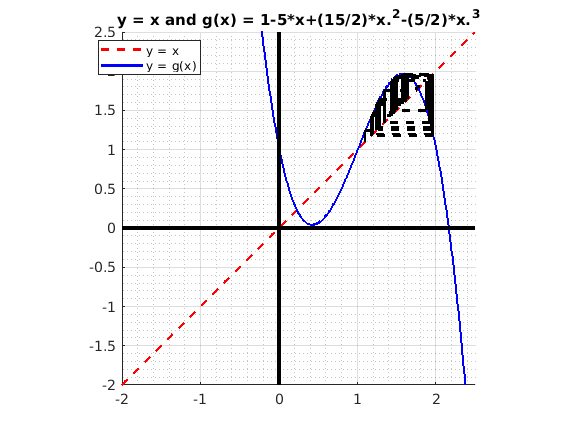

% for x -> 1 from the right we still get cyle
% around 1.7745
plotCobwebInterval(g, -2, 2.5, 1.1)

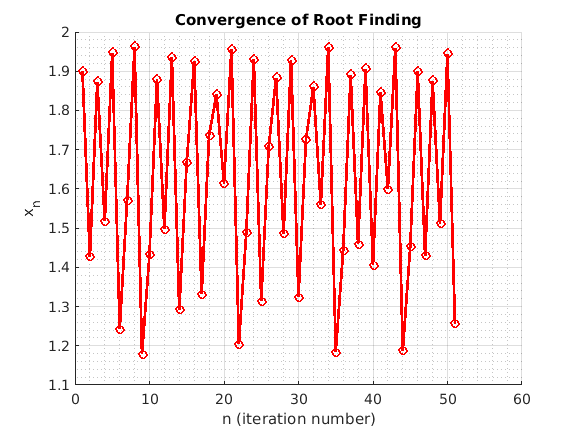

plotConvergence(x)

For x > 2 (to 2 from the right, we get cycle around 0.225)

[~, x] = fixedPointRoot(g, 2.1, 10);

n = 50, solution = 0.33486536711


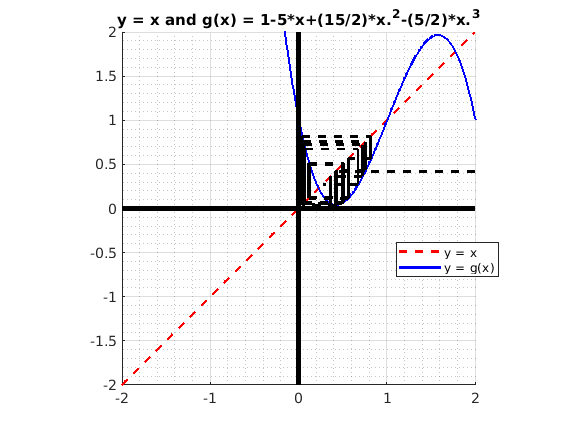

plotCobwebInterval(g, -2, 2, 2.1)

For x > 2 but increasing, we get Inf (so positive divergence)

[~, x] = fixedPointRoot(g, 2.2, 10);

n = 50, solution = NaN


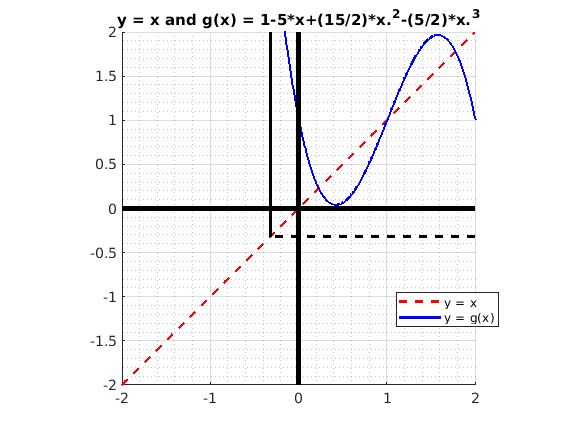

plotCobwebInterval(g, -2, 2, 2.2)

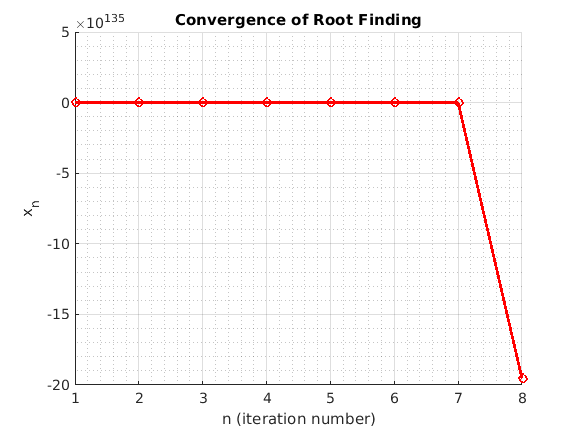

plotConvergence(x) % even though it shows negative

% here it actually is going to Inf. 